# Assignment 1: Bike Update Extension

Use a loops (for and while) to run thbike_update script repeatedly.

## Intitial Setup

Set the pre-conditions for the script

m = 100;
pg = 100;

Select figure #1 - create if it doesn't yet exist.  

figure;

## Loop 

Execute a block of code a fixed number of times.

Add a maker for each step

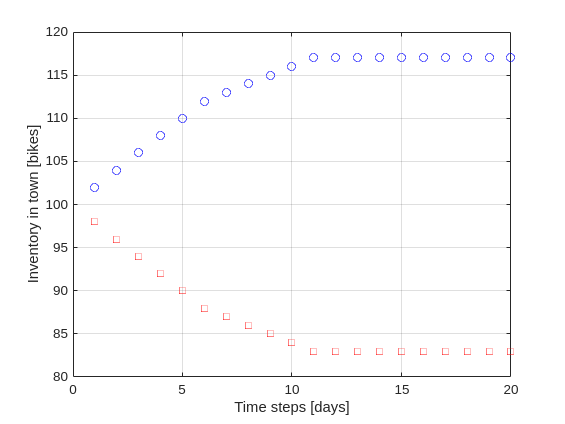

n = 20;
for ii = 1:n
    % bike update
    m_to_pg = round(0.05*m) - round(0.03*pg);
    %m_to_pg = 0.05*m - 0.03*pg;
    m = m - m_to_pg;
    pg = pg + m_to_pg;

    plot(ii, pg, 'bo');
    hold on
    plot(ii, m, 'rs');
end
xlabel('Time steps [days]')
ylabel('Inventory in town [bikes]')
grid('on')

m+pg

ans = 200

## Loop and Vector

Repeat the loop, but store all the results as a vector.

Initialize vector witht the first element 

m_vector(1) = 100;
pg_vector(1) = 100;

Then loop through each step and store the resutls


for ii = 1:n
    m_to_pg = round(0.05*m_vector(ii)) - round(0.03*pg_vector(ii));
    m_vector(ii+1) = m_vector(ii) - m_to_pg;
    pg_vector(ii+1) = pg_vector(ii) + m_to_pg;
end
sum([m_vector; pg_vector])

ans =    200   200   200   200   200   200   200   200   200   200   200   200   200   200   200   200   200   200   200   200   200


Plot the vector in a new figure

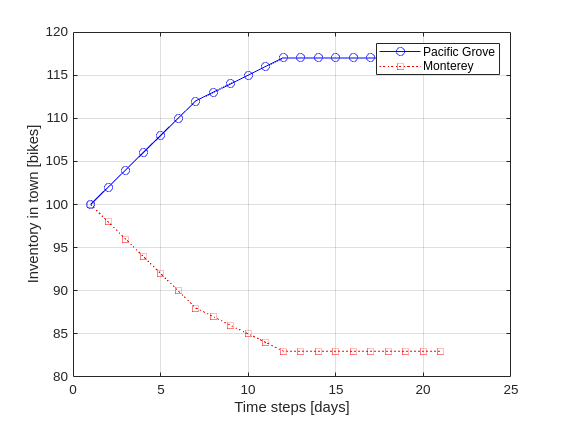

figure;
plot(pg_vector, 'bo-', 'DisplayName', 'Pacific Grove');
hold on;
plot(m_vector, 'rs:', 'DisplayName', 'Monterey');
xlabel('Time steps [days]')
ylabel('Inventory in town [bikes]')
grid('on')
legend()

A new section allows us to see both legend options.

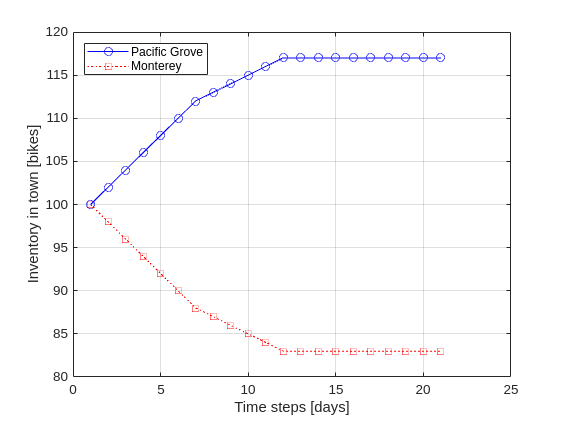

legend('Location','northwest')